# 1-1

clear; clc;
load('lidar_data.mat');
angle_start = -95; % Lidar의 horizontal start angle (-95 ~ 95)

angle_res1 = 0.1667; % Lidar 1의 분해능
angle_res23 = 0.5; % Lidar 2, 3의 분해능

angle1 = angle_start : angle_res1 : angle_start + angle_res1 * 1140;  
angle23 = angle_start : angle_res23 : angle_start + angle_res23 * 380; 



# 1-2

% Lidar를 한 사람이 본 것처럼 회전 변환을 통해 정렬해줘야 한다.
    % �Raw data만 가지고 data를 그릴 수는 없다.
    % Raw Data로 시간에 따른 거리 data(mm)가 들어올텐데 정확히 어디에서 들어온 곳인지를 알기 위해 회전 변환.
    % 개구각이 -95 ~ 95도임을 알고 있고,
    % angle resolution도 알고 있다. (L1 : 0.1667 / L2,3 : 0.5) (degree)
    % 개구각과 angle resolution을 미리 알고 있으니까. 
    % Raw Data에 대해 선형변환을 통해 물체가 어디에 위치해 있는지를 정확히 알 수 있어서 선형 변환.

% Lidar 1
x1 = cosd(angle1).*(lidar_data_1 / 1000); % mm를 m로 단위로 변환하기 위해
y1 = sind(angle1).*(lidar_data_1 / 1000);
z1 = zeros(1,length(x1));

% Lidar 2
x2 = cosd(angle23).*(lidar_data_2 / 1000); 
y2 = sind(angle23).*(lidar_data_2 / 1000); 
z2 = zeros(1,length(x2));

% Lidar 3
x3 = cosd(angle23).*(lidar_data_3 / 1000); 
y3 = sind(angle23).*(lidar_data_3 / 1000); 
z3 = zeros(1,length(x3));


# 1-3

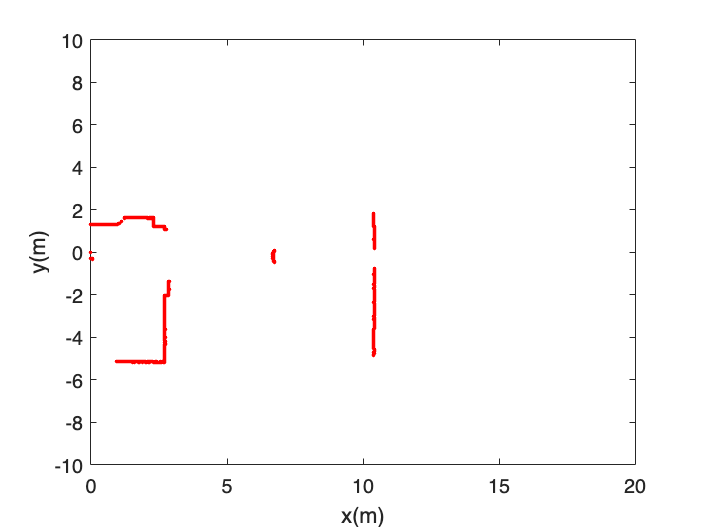

figure; 
plot(x1,y1,'r.'); 
axis ([0 20 -10 10]);
xlabel('x(m)'); 
ylabel('y(m)'); 

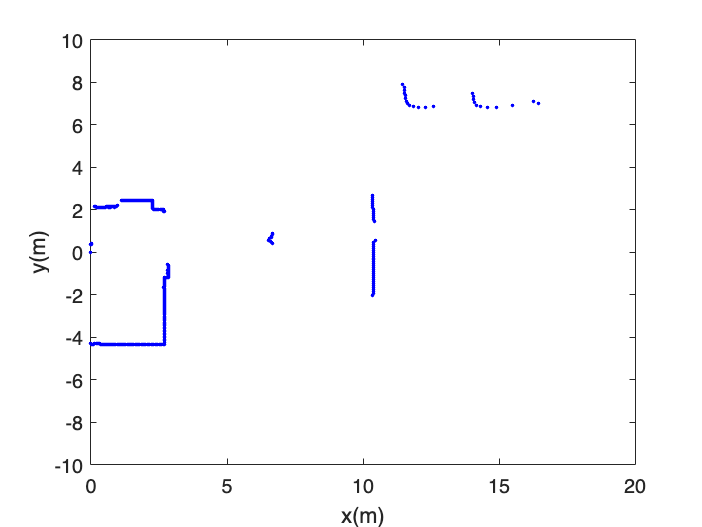


figure; 
plot(x2,y2,'b.');
axis ([0 20 -10 10]); 
xlabel('x(m)'); 
ylabel('y(m)');

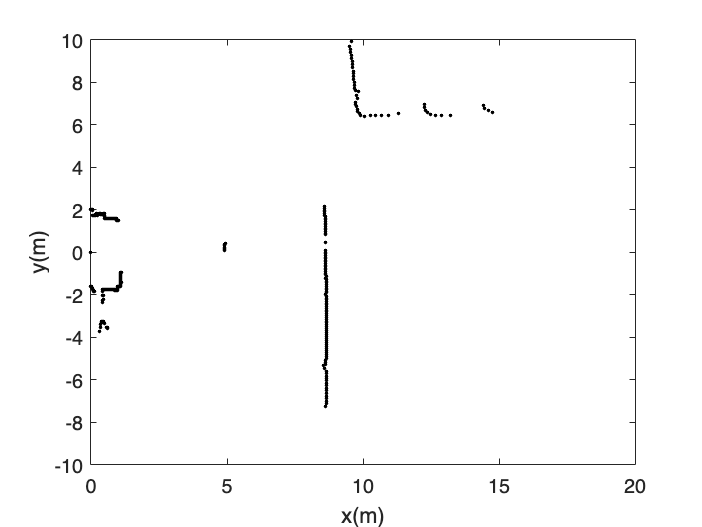


figure; plot(x3,y3,'k.');
axis ([0 20 -10 10]); 
xlabel('x(m)');
ylabel('y(m)');

# 1-4

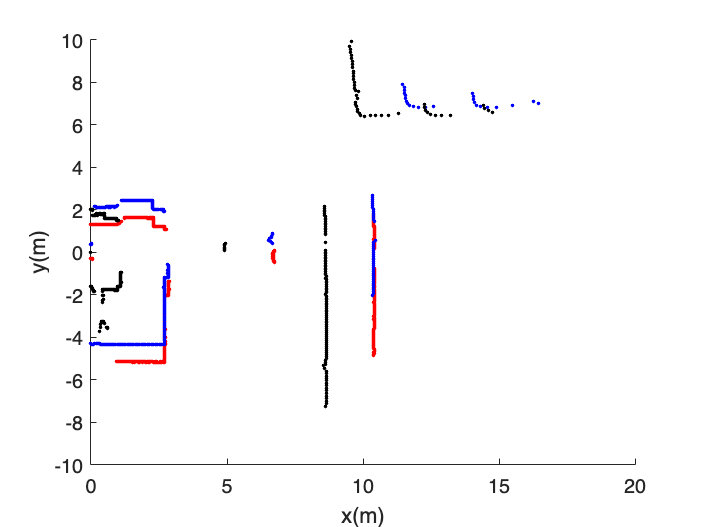

figure; hold on; axis ([0 20 -10 10]);

plot(x1,y1,'r.');
plot(x2,y2,'b.');
plot(x3,y3,'k.'); 

xlabel('x(m)'); 
ylabel('y(m)');